%clear all
%Runs the Tracking Algorithm using the inputs of the select_area_
%Callback and the frame select input

%Load data
clear
close all %to make sure only the data from this time is shown
%select file
disp('Select -mat file containing ultrasound data\n')

Select -mat file containing ultrasound data\n


fil = uigetfile;            % open dialog box to choose file
data = load(fil);           % load file into struct
%change from struct to 3D matrix
names=fieldnames(data); %extract names of each frame
len=length(names); %find # of frames
[r, c]=size(eval(['data.' names{1}])); %find size of each matrix
mat=zeros(r,c,len); %preallocate
for i=1:len
    mat(:,:,i)=eval(['data.' names{i}]); %enter frame information
end
fprintf([fil ' loaded\n']) %tell user file loaded

n_rmed_2-2.mat loaded


clear i data names %clear variables no longer needed
%convert from RF to amplitude
htf=zeros(r,c,len); %preallocate
for i=1:len
    htf(:,:,i)=hilbert(mat(:,:,i)); %find hilbert transform of each frame
end
hamp=abs(htf); %hamp is the analytic envelope
ctr=5; %compression parameter
amp=20*log10(hamp/ctr); %amplitude in dB


%Create Kernal and St
x1 = 100; y1 = 500; w = 50; h = 450;
%{
% For the GUI

% get st from the handles of the area function
st =
%Get the Template and Target frames/ data from slider
%get handles.f from slider1_Callback
tar=
temp=
%search range
sX=10;
sY=10;
%how much of the ROI to search
%
rX=st.h;
cY=st.w;
%}
initstate = [x1, y1, w, h];
st = state(initstate);
% Put things together in a struct, and check the integrity
%search range
sX=50;
sY=40;
%how much of the ROI to search
rX=h;
cY=w;
method = [sX, sY, rX, cY];
kn = kernel(method,st);

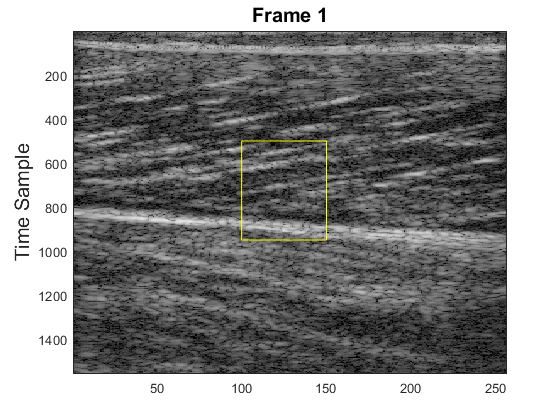


%Frame Selection 
%select start frame\
%try nr med and nr lat nrmed is the best
%fprintf('try frame 66 -74 for e_rlat_2-2')
f=input(['Select start frame between 1 and ' num2str(len) ': ']);
if f<1 || f>len
    f=input('Error: select number in range: ');
end
   
    % %display first frame image
    %fprintf(['Displaying frame ' num2str(f) '\n']);
    h=figure;
    i1=image(amp(:,:,f));
    colormap(gray)
    fs=num2str(f);
    title(['Frame ' fs],'FontSize',15)
    ylabel('Time Sample','FontSize',15)
    rectangle('Position',initstate,'EdgeColor','y')

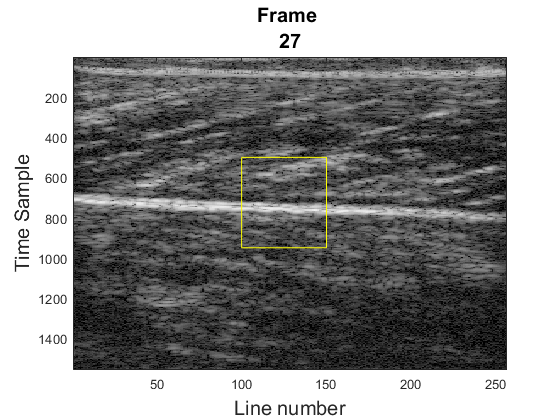

%select 2nd frame
f2=input(['Select 2nd frame between 1 and ' num2str(len) ': ']);
if f2<1 || f2>len
    f2=input('Error: select number in range: ');
end

%fprintf(['Displaying frame ' num2str(f2) '\n']);
h2=figure;
i2=image(amp(:,:,f2));
colormap(gray)
fs2=num2str(f2);
title(["Frame " fs2],'FontSize',15)
xlabel('Line number','FontSize',15)
ylabel('Time Sample','FontSize',15)
rectangle('Position',initstate,'EdgeColor','y')

%generates the Target and template
templ= mat(:,:,f);
tar= mat(:,:,f2);
%Performs NCorr to
data = NCorrEst(templ,tar,st,kn);

% Create the quiver
fig_quiv=figure;
qdata=quiver(data.v, data.u);
disp(["sX " sX "sY " sY] )

    "sX "    "50"    "sY "    "40"



title('quiver of Temp to Tar')
%qdata.Visible= 'off';

%Creating the mean vector of entire ROI
fakeu=zeros(size(data.v));
fakev=fakeu;
midx=round(rX/2);
midy=round(cY/2);

nonz_u= data.u((data.u ~= 0));
meanu=mean(nonz_u);
disp(["meanu:" meanu])

    "meanu:"    "-1.7842"




nonz_v= data.v((data.v ~= 0));
meanv=mean(nonz_v);
disp(["meanv:" meanv])

    "meanv:"    "-1.3817"





fakeu(midx,midy)=meanu;
fakev(midx,midy)=meanv;

%plotting the mean vector of the entire ROI
hold on
qdata2=quiver(fakev,fakeu);
qdata2.LineWidth=3;
qdata2.AutoScaleFactor=9;
qdata2.MaxHeadSize=7;
xlim([0 initstate(3)])
%qdata2.Visible='off';
%xlim([12 25])
%ylim([initstate(4) 0])


%Plots the mean vectors of the Cart. top and bot
%Cart Top half
fakeu1=zeros(size(data.v));
fakev1=fakeu1;
cart_yhalf=round(rX/2);
cart_topmidy=round(cart_yhalf/2);
cart_xhalf=round(cY/2);

topu=data.u(1:rX,1:cart_xhalf);
topv=data.v(1:rX,1:cart_xhalf);
 
nz_topu=topu(topu~=0);
meanu1= mean(nz_topu);

nz_topv=topv(topv~=0);
meanv1= mean(nz_topv);

fakeu1(cart_topmidy,cart_xhalf)=meanu1;
fakev1(cart_topmidy,cart_xhalf)=meanv1;

disp(["meanu1:" meanu1])

    "meanu1:"    "0.078788"



disp(["meanv1:" meanv1])

    "meanv1:"    "-1.4049"



topq=quiver(fakev1,fakeu1);
topq.AutoScaleFactor= 9;
topq.LineWidth=3;

%Cart. bot half
fakeu2=zeros(size(data.v));
fakev2=fakeu2;
cart_botmidy=cart_yhalf+cart_topmidy;
botu=data.u(1:rX,cart_xhalf:cY);
botv=data.v(1:rX,cart_xhalf:cY);

nz_botu=botu(botu~=0);
meanu2= mean(nz_botu);

nz_botv=botv(botv~=0);
meanv2= mean(nz_botv);


fakeu2(cart_botmidy,cart_xhalf)=meanu2;
fakev2(cart_botmidy,cart_xhalf)=meanv2;
disp(["meanu2:" meanu2])

    "meanu2:"    "-3.4217"



disp(["meanv2:" meanv2])

    "meanv2:"    "-1.1648"



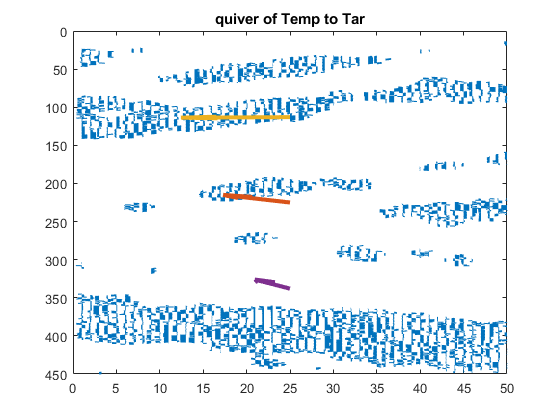

botq=quiver(fakev2,fakeu2);
botq.AutoScaleFactor= 9;
botq.LineWidth=3;

set(gca,'Ydir','reverse')
hold off


%could do an area selection thing 
%to find the mean for each area
%finds the upperleft cords and the square
%does inequality to grab 
%both u and v of data points within

